# 2-Dimensional $H_\infty$ Controller for Canted-Rotors Octocopter

## System equations

The equations of motion are defined as:

$\ddot{x} =  \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \sin\theta + (T_{xb} + F_{xb})\cos\theta \, \big)$,

$\ddot{z} = \frac{1}{m_\mathrm{UAV}} \big( \, (T + F_{zb}) \cos\theta + (T_{xb} + F_{xb})\sin\theta \, \big) + g$,


$$\ddot{\theta} = \frac{1}{J_\mathrm{UAV}} ( M + M_\mathrm{aero} )$$


where $T$ and $T_{xb}$ represent the vertical and horizontal forces produced by the UAV's rotors. Likewise, $M$ represents the pitching moment applied by differencial rotor commands. These forces and moment are defined as

$T = - C_T \cos\zeta \sum_{i=1}^8 {\omega_i}^2$,

$T_{xb} = 2 C_T \sin\zeta ( {\omega_3}^2 - {\omega_2}^2 )$,


$$M = 2 C_T D_\mathrm{UAV} \cos\zeta \left( {\omega_1}^2 \sin 22.5^\circ + {\omega_2}^2 \cos 22.5^\circ - {\omega_3}^2 \cos 22.5^\circ -{\omega_4}^2 \sin 22.5^\circ \right)$$


where $C_T$ is the rotors' coeffcient of lift, $\zeta$ is the cant angle of the motors, $D_\mathrm{UAV}$ is the distance between opposite pairs of rotors, and $\omega_i$ is the rotational speed of rotor $i$. The rotor numbers are shown in Figure 1b.

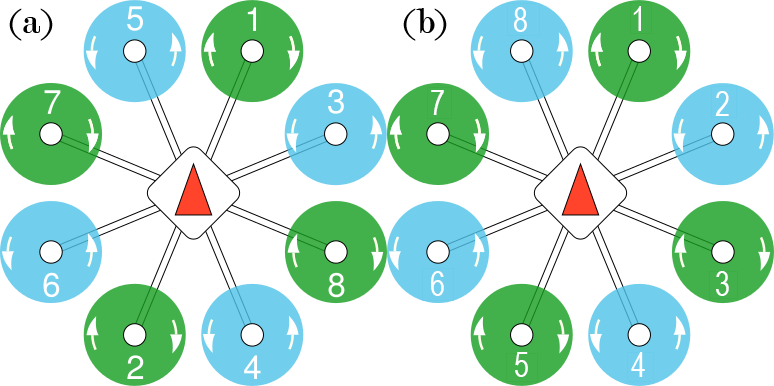

**Figure 1:** Rotor numbers (a) as seen by PX4 firmware, (b) used for modelling the system. **[Rotor directions might need to be inverted]**

The other forces acting on the UAV, $F_{zb}$ and $F_{xb}$, are vertical and horizontal aerodynamic forces. Likewise, $M_\mathrm{aero}$ is an aerodynamic pitching moment. These forces and moment are defined as

$F_{xb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{xb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{xb,2} U \bar{\omega}$,

$F_{zb} = \frac{1}{2} \rho A_\mathrm{UAV} C_{zb,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} D_\mathrm{prop} \frac{n}{4} C_{zb,2} U \bar{\omega}$,


$$M_\mathrm{aero} = \frac{1}{2} \rho A_\mathrm{UAV} D_\mathrm{UAV} C_{M,1} U^2 +  \frac{1}{2} \rho A_\mathrm{prop} {D_\mathrm{prop}}^2 \frac{n}{4} C_{M,2} U \bar{\omega}$$


where $U$ is the effective wind speed acting on the UAV and $\bar{\omega}$ is the mean rotor speed. $n$ is the number of rotors, $\rho$ is the air density, $A_\mathrm{UAV}$ and $A_\mathrm{prop}$ are representative areas for the UAV and rotor respectively and $D_\mathrm{prop}$ is the diameter of a propeller. $C_{xb,1}$, $C_{xb,2}$, $C_{zb,1}$, $C_{zb,2}$, $C_{M,1}$, and $C_{M,2}$ are dimensionless aerodynamic coefficients defined as

$C_{xb,1} = -0.241\cos\alpha + 0.036\cos(3\alpha) + 0.016\cos(7\alpha)$,

$C_{xb,2} = -0.053\cos\alpha - 0.008\cos(3\alpha)$,

$C_{zb,1} = -0.724\sin\alpha + 0.080$,

$C_{zb,2} = -0.222\sin\alpha + 0.065$,

$C_{M,1} =  0.009\cos\alpha + 0.003\cos(3\alpha) - 0.014\sin(2\alpha)$,

$C_{M,2} =  A_1\cos\alpha + A_2\sin(2\alpha)$,

where $\alpha$ is the angle of attack of the wind. $A_1$ and $A_2$ are defined as

$A_1  =  0.116 ( 1 - e^{-0.126\lambda} )$,


$$A_2  = -0.041 ( 1 - e^{-0.308\lambda} )$$


where


$$\lambda = \frac{\bar{\omega} D_\mathrm{prop} }{ 2 U }$$


is the mean rotor tip-speed ratio.

## $H_\infty$ Controller Definition

Following the conventions highlighted in [1], the standard $H_\infty$ controller is shown in Figure 2.

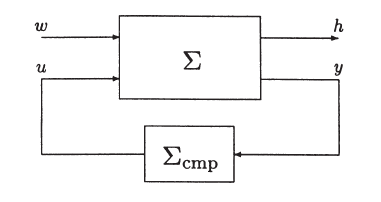

**Figure 2:** The standard $\mathcal{H}_\infty$-optimization problem. Retrieved from [1].

The plant and controller (compensator), $\Sigma$ and $\Sigma_\mathrm{cmp}$ respectively, are defined as


$$\Sigma :
\begin{cases}
\dot{\mathbf{x}} = \mathbf{A} \mathbf{x} + \mathbf{B} \mathbf{u} + \mathbf{E} \mathbf{\omega} \\
\mathbf{y} = \mathbf{C}_2 \mathbf{x} + \mathbf{D}_1 \mathbf{\omega}\\
\mathbf{h} = \mathbf{C}_1 \mathbf{x} + \mathbf{D}_{2} \mathbf{u}  + \mathbf{D}_{22} \mathbf{\omega}
\end{cases} \enspace,$$



$$\Sigma_\mathrm{cmp} :
\begin{cases}
\dot{\mathbf{v}} = \mathbf{A}_\mathrm{cmp} \mathbf{v} + \mathbf{B}_\mathrm{cmp} \mathbf{y} \\
\mathbf{u} = \mathbf{C}_\mathrm{cmp} \mathbf{v} + \mathbf{D}_\mathrm{cmp} \mathbf{y}
\end{cases} \enspace.$$


where $\mathbf{x}$ is the state vector, $\mathbf{h}$ is the control output vector, $\mathbf{\omega}$ is noise input vector, and $\mathbf{u}$ is the input vector.

## Creation of a Simple Controller

We first create the simplest controller possible. For the sake of this controller, we completely disregard the dynamics of the controller and motors. We assume we can directly control the mean rotor forces $T_R$, the horizontal thrust, $T_{R,xy}$, and a pitching moment $M_R$ 

$\mathbf{u} = \left[\matrix{ T_R & T_{R,xy} & M_R} \right]^\top$ .

Next, we choose the state variables. As we disregarded all extraneous dynamics, we are left with two double integrators:

$\mathbf{x} = \left[\matrix{ x & \dot{x} & z & \dot{z}}\right]^\top$.

The disturbance input is chosen as the wind speed, $U$. The disturbance vector can also be used to model uncertainties but we keep things as simple as possible.

$\mathbf{\omega} = U$.

We include the system states in the regulated output vector since those are the states we want to regulate. In addition, in order to try to minimise the magnitude of the inputs, we include them in the regulated output.

$\mathbf{h} = \left[\matrix{ \mathbf{x} & \mathbf{u} }\right]^\top = \left[\matrix{ x & \dot{x} & z & \dot{z} & T_R & T_{R,xy} & M_R  }\right]^\top$.

From this, we can already define the $\mathbf{C}_1$, $\mathbf{D}_2$, and $\mathbf{D}_{22}$ matrices as

$\mathbf{C}_1 =  \left[\matrix{ \mathbf{A} \cr \mathbf{0} } \right], \mathbf{D}_2 = \left[\matrix{ \mathbf{0} \cr \mathbf{B} } \right], \mathbf{D}_{22} =  \left[\matrix{ \mathbf{E} \cr \mathbf{0} } \right]$.

We are not modelling noise and we assume that all states are available, therefore

$\mathbf{C}_2 = \mathbf{I}, \mathbf{D}_1 = \mathbf{0}$.

We then use MATLAB to linearise our simplified simulink model to obtain the $\mathbf{A}$, $\mathbf{B}$ and $\mathbf{E}$ matrices.

## References

- Chen, B. M. $\mathcal{H}_\infty$ Control and Its Applications. *Springer, ***1998***, 235*